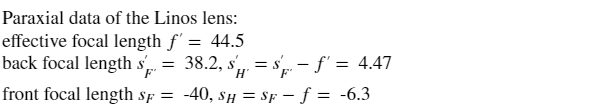

addpath(genpath('C:\Users\locsupp\Downloads\RTTB_v10\documented')) % Add folder and all subfolders of RTTB to search path

% Number of surfaces (including sensor surface)        
linos_f44.n_surf=8;
% Curvatures of lens surfaces:
linos_f44.c=[1/14.1;  0;  1/-29.6; 1/13.0; 1/-91.1;  1/14.57;  1/-21; 0];
% Distances from surface to surface:
linos_f44.d=[10;  2.76;  1.94;  1.49;  1.9;  1.07;  2.9;  38.19];
% Glasses (Schott): SK4;  F8;  KZFN2;  LAK31;
% Refraction indices at specified wavelengths:
linos_f44.la=0.00053; % wavelength of lab experiment
linos_f44.n=[1.0; 1.6163353; 1.0; 1.6007627; 1.0; 1.5329841; 1.7010020; 1.0];
% Typ of surface (a=0: spherical surface):
linos_f44.a=[0; 0; 0; 0; 0; 0; 0; 0;];
% Heights of surfaces
linos_f44.h=[5.5;  5.5;  5.0; 5.0;  5.5;  5.5;  5.5;  16.77];
% Max. field angle
linos_f44.w=22*pi/180;

% Position of the stop
d_stop=sum(linos_f44.d(1:4))+0.64; % data sheet: sum(linos_f44.d(1:4))
h_stop=4.07; % data sheet: 4.04

% Calculate entrance pupil from stop
[linos_f44.d_P, linos_f44.l_P]=find_EP(linos_f44.n_surf, linos_f44.d, linos_f44.c, linos_f44.n, d_stop, h_stop);

[efl_linos_f44, bfl_linos_f44, ffl_linos_f44]=par_data_basic(linos_f44.n_surf, linos_f44.c, linos_f44.d, linos_f44.n);
s_H=bfl_linos_f44-efl_linos_f44;
s_H_q=ffl_linos_f44+efl_linos_f44;

figure('Position',[1 1 500 90]), set(gca,'position',[0 0 1 1]), axis off
text(0,0,...
    {'Paraxial data of the Linos lens:' ...
    ['effective focal length $f'' =$ ' num2str(efl_linos_f44,3)] ...
    ['back focal length $s''_{F''} =$ ' num2str(bfl_linos_f44,3) ', $s''_{H''}=s''_{F''}-f'' =$ ' num2str(s_H_q,3)] ...
    ['front focal length $s_{F} =$ ' num2str(ffl_linos_f44,3) ', $s_{H}=s_{F}-f =$ ' num2str(s_H,3)]}, ...
    'VerticalAlignment', 'bottom', 'FontSize',12,'Interpreter', 'latex')

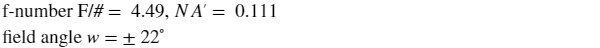


NA_q= linos_f44.l_P/efl_linos_f44;
figure('Position',[1 1 500 40]), set(gca,'position',[0 0 1 1]), axis off
text(0,0,...
    {'Data of the Linos lens:' ...
    ['f-number F$/\# =$ ' num2str(efl_linos_f44/2/linos_f44.l_P,3) ', $NA''=$ ' num2str(NA_q,3) ],...
    ['field angle $w = \pm$ ' num2str(linos_f44.w/pi*180,3) '$^\circ$']},...
    'VerticalAlignment', 'bottom', 'FontSize',12,'Interpreter', 'latex')

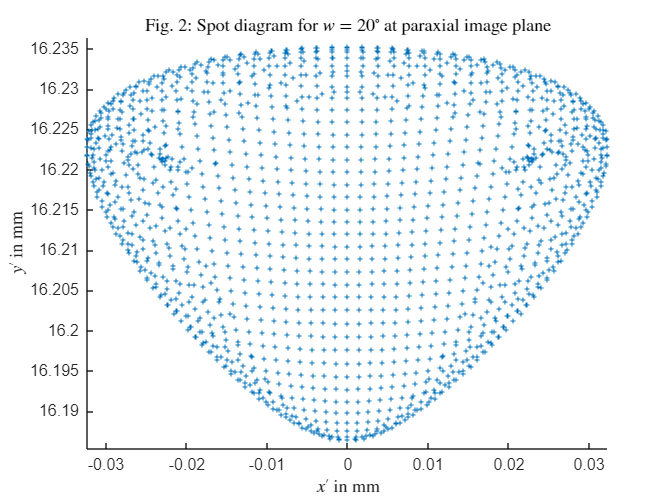


% w=0; % field angle
w=20/180*pi; 
N_trace_sq=51; % square root of number of rays

warning off
[r_pos,r_dir,OPL]=spot_diag_inf(linos_f44, w, N_trace_sq);
warning on 

figure()
line(r_pos(1,:),r_pos(2,:), 'LineStyle', 'none', 'Marker', '+', 'MarkerSize',3); axis equal
xlabel('$x''$ in mm','Interpreter','Latex'), ylabel('$y''$ in mm','Interpreter','Latex')
title(['Fig. 2: Spot diagram for $w=$' num2str(w/pi*180) '$^\circ$ at paraxial image plane'],'Interpreter','Latex');

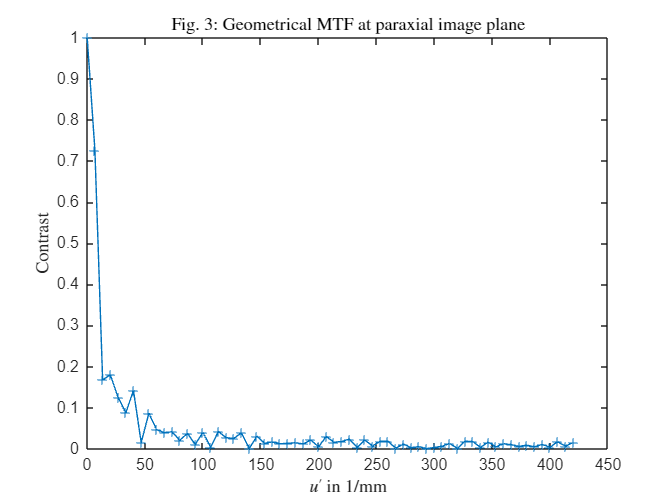


uv_max=2*NA_q/linos_f44.la(1);
N_u=64; % number of spatial frequency samples
dir='x'; % direction in the image plane ('x' or 'y')
[otf_g, u_q_sim]=otf_geom(r_pos,N_u, uv_max, dir); 
if dir == 'x', dir_uv='u'; elseif dir=='y', dir_uv='v'; end

figure()
plot(u_q_sim, abs(otf_g),'Marker', '+')
xlabel(['$' dir_uv '''$ in 1/mm'],'Interpreter','Latex'), ylabel('Contrast','Interpreter','Latex')
title('Fig. 3: Geometrical MTF at paraxial image plane','Interpreter','Latex')

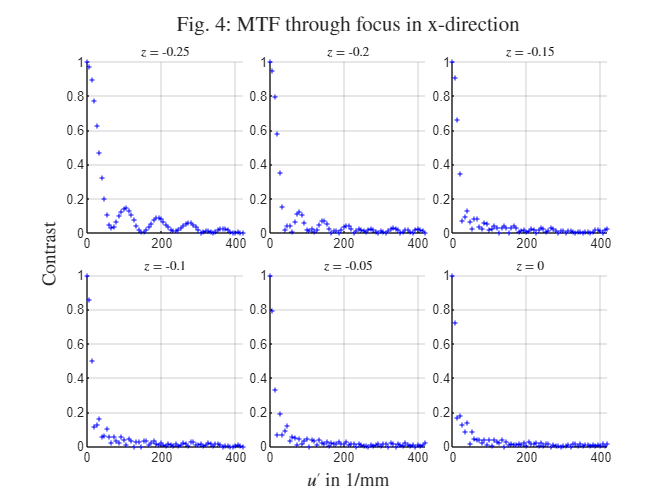


z_min=-0.25; z_max=-0.0;
m_tile=2;n_tile=3;
z_tf=linspace(z_min,z_max,m_tile*n_tile);
[otf_tf, f]=otf_geom_tf(r_pos,r_dir, z_tf, N_u, uv_max, dir);

figure()
t=tiledlayout(m_tile,n_tile,'TileSpacing','Compact');
for i_z=1:m_tile*n_tile
    nexttile
    line(f,abs(otf_tf(i_z,:)),'Color', 'b', 'LineStyle', 'none', 'Marker', '+', 'MarkerSize',3)
    set(gca,'ylim',[0 1]); set(gca,'FontSize',8); title(['$z=$', num2str(z_tf(i_z), 3)],'FontSize',8,'Interpreter','latex');
    grid on
end
xlabel(t,['$' dir_uv '''$ in 1/mm'],'Interpreter','Latex'), ylabel(t,'Contrast','Interpreter', 'latex')
title(t,['Fig. 4: MTF through focus in  ' dir '-direction'], 'Interpreter', 'latex')


if w==0
    dir_rms='xy'; % dir for minimum rms-size ('xy', 'x, or 'y')
else
    dir_rms=dir; % dir for minimum rms-size ('xy', 'x, or 'y')
end
pos_rms=plane_min_rms(r_pos, r_dir, dir_rms); 
d_z=pos_rms(3); % defocus
disp(['Defocus for minimum spot size: ' num2str(d_z,3)])

Defocus for minimum spot size: -0.327


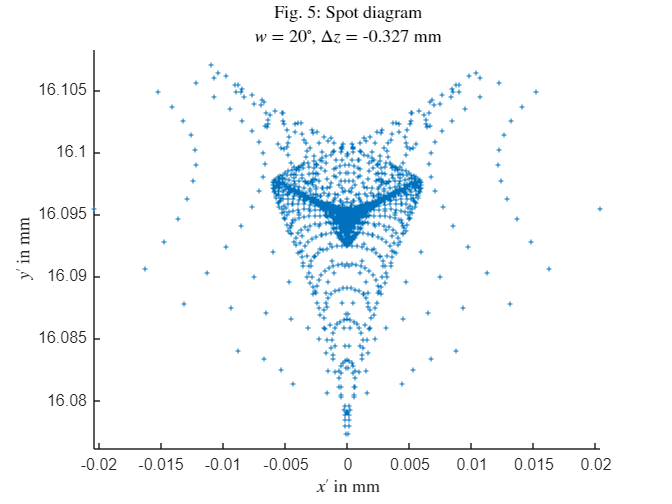


r_dz_pos=r_pos+r_dir(1:2,:)./repmat(r_dir(3,:),2,1)*d_z; % spots at defocus
OPL_dz=OPL+linos_f44.n(linos_f44.n_surf,1)*d_z./r_dir(3,:); 
% set image plane to the desired value:
linos_f44.d(end)=bfl_linos_f44+d_z;

figure()
line(r_dz_pos(1,:),r_dz_pos(2,:), 'LineStyle', 'none', 'Marker', '+', 'MarkerSize',3); axis equal
xlabel('$x''$ in mm','Interpreter','Latex'), ylabel('$y''$ in mm','Interpreter','Latex')
title({['Fig. 5: Spot diagram']; ['$w= $', num2str(w/pi*180), '$^\circ$, $\Delta z=$', num2str(d_z,3), ' mm']},'Interpreter','Latex');

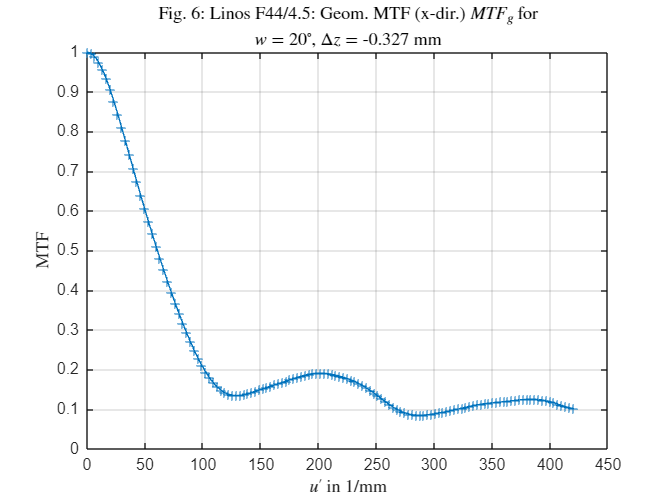


[otf_g_dz, u_q_sim]=otf_geom(r_dz_pos,2*N_u, uv_max, dir);

figure()
plot(u_q_sim, abs(otf_g_dz),'Marker', '+')
set(gca, 'Ylim', [0 1]); xlabel(['$' dir_uv '''$ in 1/mm'],'Interpreter','Latex'), ylabel('MTF','Interpreter','Latex')
title({['Fig. 6: Linos F44/4.5: Geom. MTF (' dir '-dir.) ' '$MTF_g$' ' for'], ['$w= $' num2str(w/pi*180) '$^\circ$, $\Delta z=$' num2str(d_z,3) ' mm']},'Interpreter','Latex');
grid on

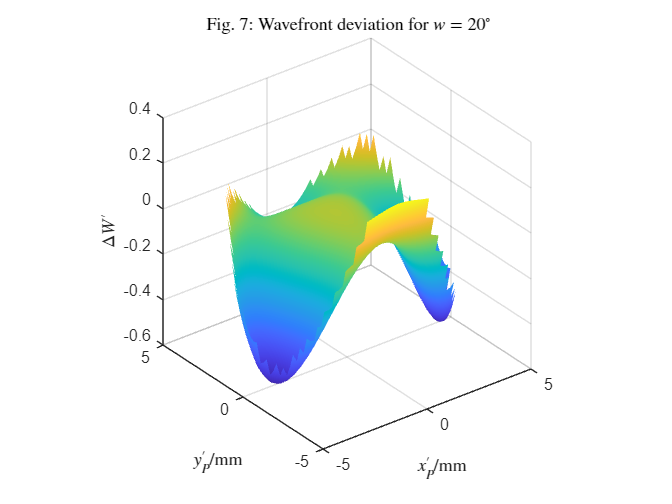


z_Pq=image_distance(linos_f44.d_P-linos_f44.d(1),linos_f44.n_surf, linos_f44.c, linos_f44.d, linos_f44.n)+sum(linos_f44.d(1:linos_f44.n_surf-1));
d_PqOq=sum(linos_f44.d(1:linos_f44.n_surf))-z_Pq; % distance from exit pupil to image plane

r_Pq_pos=r_dz_pos+r_dir(1:2,:)./repmat(r_dir(3,:),2,1)*(-d_PqOq);
OPL_Pq=OPL_dz+linos_f44.n(linos_f44.n_surf,1)*(-d_PqOq)./r_dir(3,:); 

OPD_Pq=OPL_Pq+linos_f44.n(linos_f44.n_surf,1)*...
    sqrt(r_Pq_pos(1,:).^2+(r_Pq_pos(2,:)-mean(r_dz_pos(2,:))).^2+d_PqOq^2);
% subtract constant path length
[min_pos,ind_min_pos]=min(sum(r_Pq_pos(1:2,:).^2));
OPD_Pq=OPD_Pq-OPD_Pq(ind_min_pos);

N=512; % Dimension of the regular grid
if mod(N,2) ~= 0, warning('N not even! indexing is not correct.'), end
y_max=10*max(max(abs(r_Pq_pos(1,:))),max(abs(r_Pq_pos(2,:)))); % +/- height of the amplitude distribution
dy_Pq=2*y_max/N;
y_Pq=((0:N-1)-N/2)*dy_Pq; %y-Koordinaten der AP
x_Pq=((0:N-1)-N/2)*dy_Pq; %x-Koordinaten der AP
[X_Pq,Y_Pq]=meshgrid(x_Pq,y_Pq);

OPD_Pq_I=NaN(N);
% grid indices of the exit pupil
ind_Pq_gd_x=find((x_Pq >= min(r_Pq_pos(1,:))) & (x_Pq <= max(r_Pq_pos(1,:)))); 
ind_Pq_gd_y=find((y_Pq >= min(r_Pq_pos(2,:))) & (y_Pq <= max(r_Pq_pos(2,:)))); 
warning off
OPD_Pq_I(ind_Pq_gd_y,ind_Pq_gd_x)=griddata(r_Pq_pos(1,:),r_Pq_pos(2,:),...
    OPD_Pq,X_Pq(ind_Pq_gd_y,ind_Pq_gd_x),Y_Pq(ind_Pq_gd_y,ind_Pq_gd_x), 'cubic');
warning on

dW_Pq= OPD_Pq_I/linos_f44.la(1);

figure()					
surf(X_Pq,Y_Pq,dW_Pq); shading interp		
title(['Fig. 7: Wavefront deviation for $w = $', num2str(w/pi*180), '$^\circ$'],'Interpreter','Latex'); 						
xlabel('$x''_P$/mm','Interpreter','Latex');	ylabel('$y''_P$/mm','Interpreter','Latex');	zlabel('$\Delta W''$','Interpreter','Latex'); axis square		

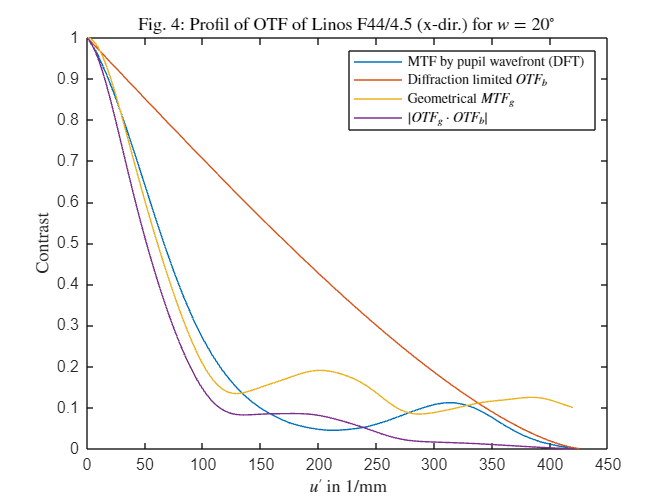


A_Pq=zeros(N);
ind_p_q=find(~isnan(dW_Pq));
Tq=1; % homogenous illumination inside of exit pupil
A_Pq(ind_p_q) = Tq*exp(j*2*pi*dW_Pq(ind_p_q));

A_q=fftshift(fft2(ifftshift(A_Pq))); 
A_q=A_q/sum(sum(abs(A_Pq))); % normalization to constant power 
PSF=abs(A_q).^2; % irradiance

dy_q=d_PqOq*linos_f44.la(1)/(dy_Pq*N);
y_q=((0:N-1)-N/2)*dy_q;
x_q=((0:N-1)-N/2)*dy_q;

OTF = fftshift(fft2(ifftshift(PSF))); % calculate OTF by DFT oft PSF
OTF=OTF/sum(sum(abs(PSF))); % normalization

du_q=1/dy_q/N;
u_q=((0:N-1)-N/2)*du_q;
v_q=((0:N-1)-N/2)*du_q;

if dir == 'x'
    l_Pq=(max(r_Pq_pos(1,:))-min(r_Pq_pos(1,:)))/2; %Index of limiting spatial frequency
elseif dir == 'y'
    l_Pq=(max(r_Pq_pos(2,:))-min(r_Pq_pos(2,:)))/2;
end
N_max=fix(2*l_Pq/dy_Pq); %Index of limiting spatial frequency
ind_profile=N/2+1:N/2+1+N_max;
if dir == 'x'
    OTF_profile=abs(OTF(N/2+1,ind_profile));
elseif dir == 'y'
    OTF_profile=abs(OTF(ind_profile,N/2+1));
end

u_q_profile=u_q(ind_profile);

NA_q=l_Pq/d_PqOq;
u_q_max=2*NA_q/linos_f44.la(1);
OTF_b=real(1/pi*(2*acos(abs(u_q_profile)/u_q_max)-sin(2*acos(abs(u_q_profile)/u_q_max)))); % ideal OTF (= FT{Airy})

figure()
plot(u_q_profile,OTF_profile, u_q_profile, OTF_b, ...
    u_q_sim,abs(otf_g_dz), ...
    u_q_sim,abs(otf_g_dz.*real(1/pi*(2*acos(abs(u_q_sim)/u_q_max)-sin(2*acos(abs(u_q_sim)/u_q_max))))))
legend({'MTF by pupil wavefront (DFT)', ...
    'Diffraction limited $OTF_b$', ...
    'Geometrical $MTF_g$', ....
    '$|OTF_g \cdot OTF_b|$'},'Interpreter','Latex')
title({['Fig. 4: Profil of OTF of Linos F44/4.5 (' dir '-dir.) for $w = $', num2str(w/pi*180), '$^\circ$ ']...
    },'Interpreter','Latex')
xlabel(['$' dir_uv '''$ in 1/mm'],'Interpreter','Latex')
ylabel('Contrast','Interpreter','Latex')

h_pp=0.00465; % pixel pitch
c_ff=1; % fill factor
h_pix=h_pp*sqrt(c_ff); % pixel size
TF_sensor=sinc(h_pix*u_q)'.*sinc(h_pix*v_q);
TF_sys=OTF.*TF_sensor;
